# Relative orbital motion using Hill–Clohessy–Wiltshire equations

clc
clear

const = orbitConst;

a0 = const.RE + 750; % semi-major axis, km
n = sqrt(const.GE / a0^3); % mean motion, s
T = 2 * pi / n;

% initial condition, m, m/s
xIni = [-10 -100 0 0 0 0];

tspan = 0:5:2*T;
opts = odeset('RelTol',1e-8,'AbsTol',1e-8);

[t_, x_] = ode45(@(t,x) eomHCW(t, x, n), tspan, xIni, opts);

## data handling

x = x_(:,1);
y = x_(:,2);
z = x_(:,3);
vx = x_(:,4);
vy = x_(:,5);
vz = x_(:,6);

## show figures

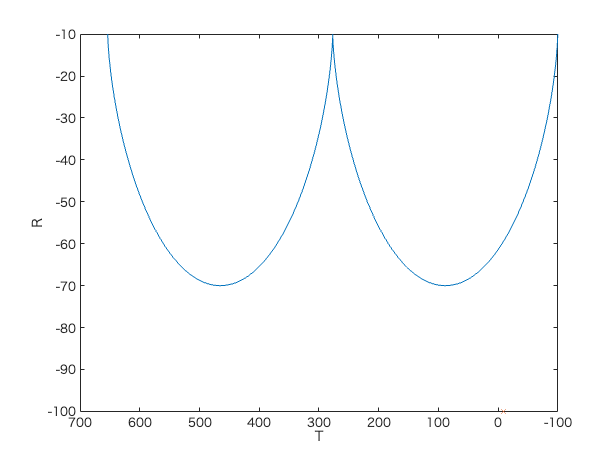

figure
plot(y, x), hold on
plot(xIni(1), xIni(2), 'x')
xlabel('T'), ylabel('R')
set(gca, 'XDir', 'reverse')